# Nelder-Mead method

## Initialization

tic
n = 2 % dimensions

n = 2

max_iterations = 100000 % max_iteration

max_iterations = 100000

value_error = 1e-9;
simplex_error = 1e-9;

%plots
figure(1);
[X,Y] = meshgrid(-10:0.1:0,-10:0.1:0);
circle = 25 - (X + 5).^2 - (Y + 5).^2;
contourf(X,Y,circle,[0,0]); axis equal; hold on;

alpha = 1 % reflection

alpha = 1

gamma = .5 % expansion

gamma = 0.5000

beta= 0.4 % contraction

beta = 0.4000

vertices = 6 * (rand(n+1,n) - 0.5) - 5 % simplex vertices
init_vert = vertices;
% vertices = init_vert;
values = f(vertices)

values =   -60.7886
    4.8053
   -0.1375


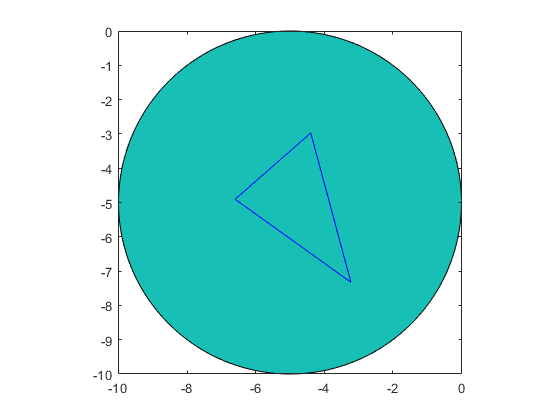

oracle_calls = n + 1;

%plots
obj = zeros(max_iterations+1,1); %vol = zeros(max_iterations,1);
error = zeros(max_iterations+1,1); %vol = zeros(max_iterations,1);
value_criterion = false;
simpex_vol = 0;
simplex_criterion = false;
iT = 0;
triplot(delaunayTriangulation(vertices)); hold off; 
saveas(gcf,sprintf('Triangles/%i.png', iT));

## Optimization Loop

for iT=1:max_iterations 

## Sort

    [maxvalue, argmax] = max(values);
    [minvalue, argmin] = min(values);
    [greatvalue, arggreat] = max([values(1:(argmax-1));values((argmax+1):(n+1))]);
    maxvertex = vertices(argmax,:);
    minvertex = vertices(argmin,:);
    ordinar_vertices = [vertices(1:(argmax-1),:);vertices((argmax+1):(n+1),:)];
    greatvertex = ordinar_vertices(arggreat,:);
    error(iT) = abs(minvalue - maxvalue);
    obj(iT) = minvalue;
    %fprintf('No.%i, Obj:%f\n',[iT-1,obj(iT)]);

## Center of gravity

    central_vertex = mean(ordinar_vertices,1);
    central_value = f(central_vertex);
    oracle_calls = oracle_calls + 1;

## Reflection

    reflected_vertex = central_vertex + alpha * (central_vertex - maxvertex);
    reflected_value = f(reflected_vertex);
    oracle_calls = oracle_calls + 1;

## Comparison

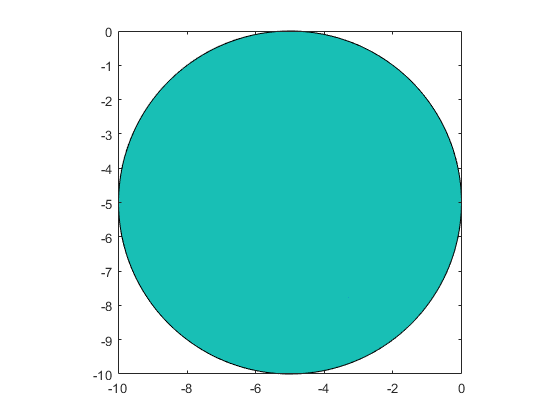

    if (reflected_value < minvalue) %4a
        % expansion
        expanded_vertex = central_vertex + gamma * (reflected_vertex - central_vertex);
        expanded_value = f(expanded_vertex);
        oracle_calls = oracle_calls + 1;
        if (expanded_value < minvalue) 
            vertices(argmax,:) = expanded_vertex;
            values(argmax) = expanded_value;
        else
            vertices(argmax,:) = reflected_vertex;
            values(argmax) = reflected_value;
        end
    elseif ((minvalue < reflected_value) && (reflected_value < greatvalue)) %4b
        vertices(argmax,:) = reflected_vertex;
        values(argmax) = reflected_value;
    elseif (((greatvalue < reflected_value) && (reflected_value < maxvalue)) || (reflected_value > maxvalue)) %4c and %4d
        if ((greatvalue < reflected_value) && (reflected_value < maxvalue)) %4c
            vertices(argmax,:) = reflected_vertex;
            values(argmax) = reflected_value;
        end
        % contraction
        contracted_vertex = central_vertex + beta * (maxvertex - central_vertex);
        contracted_value = f(contracted_vertex);
        oracle_calls = oracle_calls + 1;
        if (contracted_value <= maxvalue)
            vertices(argmax,:) = contracted_vertex;
            values(argmax) = contracted_value;
        else
            [minvalue, argmin] = min(values);
            vertices = vertices(argmin,:) + .5 * (vertices - vertices(argmin,:));
            values = f(vertices);
            oracle_calls = oracle_calls + n + 1;
        end
    end
    value_criterion = (abs(minvalue - maxvalue) < value_error);
    simpex_vol = 1 / factorial(n) * abs(det(vertices(2:n+1,:) - repmat(vertices(1,:),n,1)));
    simplex_criterion = (simpex_vol < simplex_error);
    figure(1); contourf(X,Y,circle,[0,0]); axis equal; hold on;

Elapsed time is 32.652358 seconds.


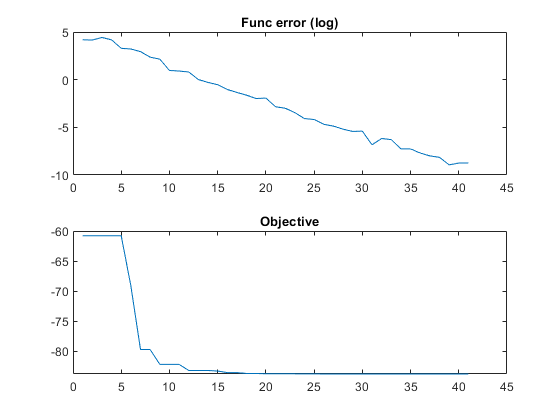

    triplot(delaunayTriangulation(vertices)); hold off; 
    saveas(gcf,sprintf('Triangles/%i.png', iT));
    if (value_criterion || simplex_criterion)
        break;
    end
end
toc
error(iT+1) = abs(minvalue - maxvalue);
obj(iT+1) = minvalue;
figure(2);  subplot(2,1,1); plot(log(error(1:iT+1)),'-'); title('Func error (log)');
            subplot(2,1,2); plot(obj(1:iT+1),'-'); title('Objective');